# Assignment 1 

# Problem 1

We try to optimize the following function defined $$\mathbf{x} \in \mathbb{R}^2,$$


$$$f(\mathbf{x}) \triangleq 3x_1 + 5x_2 -3x_3^2$$$


s.t


$$$g_1(\mathbf{x}) \triangleq 2x_1^2 - 37 x_2 +  9 x_3 = 18 $$$



$$$g_1(\mathbf{x}) \triangleq 5 x_1 - x_2 +  5 x_3^2 = 24 $$$


We beginn by defining the functions using the Symbolic Math Toolbox 


% Define Variables 
syms x1 x2 x3 lambda1 lambda2 real 

x = [x1 x2 x3]; 
lambda = [lambda1 lambda2];
xlambda = [x1 x2 x3 lambda1 lambda2];

% Define functions
syms f(x1, x2, x3) 
syms g1(x1, x2, x3)
syms g2(x1, x2, x3)
syms L(x1, x2, x3, lambda1, lambda2) 

%% objective

f(x1, x2, x3) = 3*x1 + 5*x2 -3*x3^2; % define f


%% left side of constraints
g1(x1, x2, x3) = 2*x1^2 - 37*x2 +  9*x3; 
g2(x1, x2, x3) = 5*x1 - x2 +  5*x3^2;


% right side of constraints
b1 = 18; 
b2 = 24; 
 

% define Lagrange Function:

L(x1, x2, x3, lambda1, lambda2) = f - lambda1*(g1-b1) - lambda2*(g2-b2);

## a) Analysis of the regularity of the feasible points

We than check that the the gradient of the constraint 1 can not be expressed as a linear combination of the the gradient of constraint two, to verify that the problem is well defined, that the constraints are indipendent.

%gradg1 = gradient(g1)
%gradg2 = gradient(g2)
%syms c1
%xc = [x c1]
%assume(xc, 'real')
%xnr = solve(gradg2 == c1 * gradg1, g1 == b(1), g2 == b(2), xc)

As no solution exists, the constraints are independent and the feasible points are regular.

## a) First order Necessary Conditions for local optimum

### Define Gradients

We begin bei defining the gradient of the Lagrangian function L with respect to x

gradxL = simplify(gradient(L, x))

$$gradxL(x1, x2, x3, lambda1, lambda2) = \left(\begin{array}{c} 3-4\,\lambda_{1}\,x_{1}-5\,\lambda_{2}\\ 37\,\lambda_{1}+\lambda_{2}+5\\ -9\,\lambda_{1}-6\,x_{3}-10\,\lambda_{2}\,x_{3} \end{array}\right)$$

The Gradient with respect to Lambda

gradlambdaL = simplify(gradient(L, lambda))

$$gradlambdaL(x1, x2, x3, lambda1, lambda2) = \left(\begin{array}{c} -2\,{x_{1}}^{2}+37\,x_{2}-9\,x_{3}+18\\ -5\,{x_{3}}^{2}-5\,x_{1}+x_{2}+24 \end{array}\right)$$

And the gradient of L with respect to both x and lambda.

gradL = simplify(gradient(L, xlambda))

$$gradL(x1, x2, x3, lambda1, lambda2) = \left(\begin{array}{c} 3-4\,\lambda_{1}\,x_{1}-5\,\lambda_{2}\\ 37\,\lambda_{1}+\lambda_{2}+5\\ -9\,\lambda_{1}-6\,x_{3}-10\,\lambda_{2}\,x_{3}\\ -2\,{x_{1}}^{2}+37\,x_{2}-9\,x_{3}+18\\ -5\,{x_{3}}^{2}-5\,x_{1}+x_{2}+24 \end{array}\right)$$

### Identify Optima

With the Gradients defined, we solve for the points that fulfill the first oder NC of the gradient of L and yield a total of 4 candidate points.


stat_points = solve(gradL == 0, xlambda);
pe = [stat_points.x1 stat_points.x2 stat_points.x3 stat_points.lambda1 stat_points.lambda2];
pe = double(pe) 

pe =   -12.2837    8.7251    4.3392   -0.1196   -0.5752
  -12.9401    7.4977   -4.3863   -0.1183   -0.6243
    4.9667    0.8667    0.0814   -0.1696    1.2737
   87.5297  413.6497    0.0143    0.1696  -11.2743



xA = [stat_points.x1(1) stat_points.x2(1) stat_points.x3(1)];
lambdaA = [stat_points.lambda1(1) stat_points.lambda2(1)];

xB = [stat_points.x1(2) stat_points.x2(2) stat_points.x3(2)];
lambdaB = [stat_points.lambda1(2) stat_points.lambda2(2)];

xC = [stat_points.x1(3) stat_points.x2(3) stat_points.x3(3)];
lambdaC = [stat_points.lambda1(3) stat_points.lambda2(3)];

xD = [stat_points.x1(4) stat_points.x2(4) stat_points.x3(4)];
lambdaD = [stat_points.lambda1(4) stat_points.lambda2(4)];

## c) Second order conditions for local optimum

Obtenemos la hessiana de L con respecto de x

HessxL = hessian(L, x) % SECOND ORDER ANALYSIS,  hessian doesnt depend on x, says things about global optimally 

$$HessxL(x1, x2, x3, lambda1, lambda2) = \left(\begin{array}{ccc} -4\,\lambda_{1} & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & -10\,\lambda_{2}-6 \end{array}\right)$$

y la calculamos para los candidatos a óptimo local, obteniendo los autovalores para clasificarlas:

HA = double(subs(HessxL, lambda, lambdaA)) % calc hessian for all points, pos semi definite for all x, hessian convex, point a global minimum

HA =     0.4784         0         0
         0         0         0
         0         0   -0.2480


double(eig(HA)) % eigenvalues

ans =    -0.2480
         0
    0.4784



HB = double(subs(HessxL, lambda, lambdaB)) % also global minimum

HB =     0.4731         0         0
         0         0         0
         0         0    0.2427


double(eig(HB))

ans =          0
    0.2427
    0.4731


fA = double(subs(f, x, xA))

fA = -49.7114


fB = double(subs(f, x, xB))

fB = -59.0506

fC = double(subs(f, x, xC))

fC = 19.2140


fD = double(subs(f, x, xD))

fD = 2.3308e+03


HC = double(subs(HessxL, lambda, lambdaC)) % Hessian at point C, indefinite 

HC =     0.6782         0         0
         0         0         0
         0         0  -18.7373


double(eig(HC)) % indefinite, in this topic not necessarily saddle point, depends on the tangent direction

ans =   -18.7373
         0
    0.6782



HD = double(subs(HessxL, lambda, lambdaD)) % same as with point C

HD =    -0.6783         0         0
         0         0         0
         0         0  106.7426


double(eig(HD))

ans =    -0.6783
         0
  106.7426


Preparamos el análisis de direcciones tangentes para los puntos que lo requieren

syms d1 d2 real

% Analysis of Tangent direction for points C and D 

d = [d1; d2] % vector columna de variables dj

gradg1 = gradient(g1, x) 

assume(d,'clear')

subs(gradg1' * d, x, xA) %perpendicular to gradient gradient^T*d evaluated at point xA

Definimos las direcciones d tangentes a la región factible en xA,

mediante ecuaciones implícitas:

assume(d1*(sqrt(sym(241))/4 + sym(39/4)) + d2*((5*sqrt(sym(241)))/4 + sym(39/4)) == 0)

Ahora calculamos

simplify(d.' * HA * d)
solve([d1*(sqrt(sym(241))/4 + sym(39/4)) + d2*((5*sqrt(sym(241)))/4 + sym(39/4)) == 0, d1 + d2 == 0], d)

assume(d,'clear')

subs(gradg1.' * d, x, xB)

Definimos las direcciones d tangentes a la región factible en xA,

mediante ecuaciones implícitas:

assume(- d1*(sqrt(sym(241))/4 - sym(39/4)) - d2*((5*sqrt(sym(241)))/4 - sym(39/4)) == 0)

Ahora calculamos

simplify(d.' * HB * d)
solve([- d1*(sqrt(sym(241))/4 - sym(39/4)) - d2*((5*sqrt(sym(241)))/4 - sym(39/4)) == 0, d1 + d2 == 0], d)

assume(d,'clear')

subs(gradg1.' * d, x, xC)

Definimos las direcciones d tangentes a la región factible en xA,

mediante ecuaciones implícitas:

assume((sqrt(sym(79))*d1)/2 + (sqrt(sym(79))*d2)/2 == 0)

Ahora calculamos

simplify(d.' * HC * d)
solve([(sqrt(sym(79))*d1)/2 + (sqrt(sym(79))*d2)/2 == 0, d2 == 0], d)

assume(d,'clear') % Only relevant for points D and H 

subs(gradg1.' * d, x, xD) % -> tangent direction for which this is zero

Definimos las direcciones d tangentes a la región factible en xA,

mediante ecuaciones implícitas:

assume(- (sqrt(sym(79))*d1)/2 - (sqrt(sym(79))*d2)/2 == 0) % set equal to zero for point

Ahora calculamos

simplify(d.' * HD * d) % d^t*Hessian*d, simplify for tangent directions, result: negative -> less or equal than zero -> can not be minimum only maximum
solve([- (sqrt(sym(79))*d1)/2 - (sqrt(sym(79))*d2)/2 == 0, d2 == 0], d) % solve for == 0, -> sufficient condition: negative for all directions except for d1/d2 = 0. for d2 = 0 is zero e.g. sufficient condition holds

gradf = gradient(f, x)

$$gradf(x1, x2, x3) = \left(\begin{array}{c} 3\\ 5\\ -6\,x_{3} \end{array}\right)$$

gradfA = double(subs(gradf, x, xA))

gradfA =     3.0000
    5.0000
  -26.0352


gradfB = double(subs(gradf, x, xB))

gradfB =     3.0000
    5.0000
   26.3178


gradfC = double(subs(gradf, x, xC))

gradfC =     3.0000
    5.0000
   -0.4887


gradfD = double(subs(gradf, x, xD))

gradfD =     3.0000
    5.0000
   -0.0858


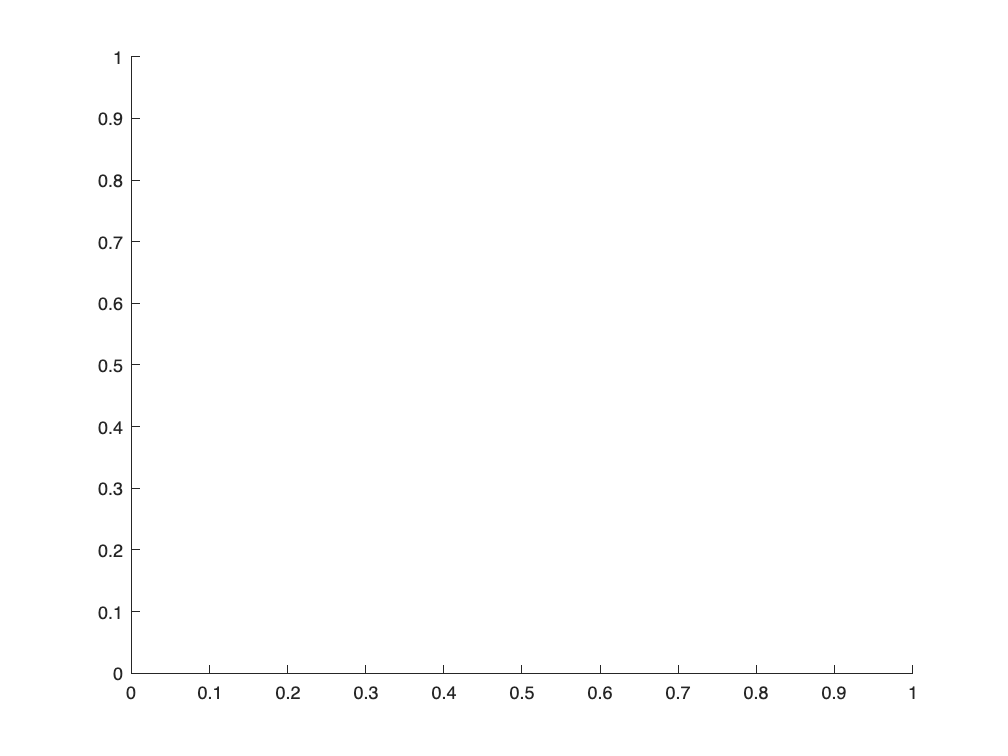

Error using fimplicit>singleFimplicit (line 185)
Input must be a function or functions of a single variable.

Error in fimplicit>@(f)singleFimplicit(cax,f,limits,extraOpts,args) (line 154)
    hObj = cellfun(@(f) singleFimplicit(cax,f,limits,extraOpts,args),fn,'Uniform

gradg1A = double(subs(gradg1, x, xA));
gradg1B = double(subs(gradg1, x, xB));
gradg1C = double(subs(gradg1, x, xC));
gradg1D = double(subs(gradg1, x, xD));
figure
rectangle = [-13 13 -12 6]; pointsize = 100; dx1 = 0.3; dx2 = 0.3;
fimplicit(g1 == b, rectangle, 'k-', 'LineWidth', 2)

hold on
fimplicit(x1 + x2 - 5 == 0, rectangle, 'm-', 'LineWidth', 2)
hold on
%fimplicit(f == fA, rectangle, 'm-', 'LineWidth', 2)
% hold on
% fimplicit(f == fB, rectangle, 'g-', 'LineWidth', 2)
% hold on
fimplicit(f == fC, rectangle, 'b-', 'LineWidth', 2)
hold on
fimplicit(f == fD, rectangle, 'c-', 'LineWidth', 2)
hold on
quiver(xC(1), xC(2), gradfC(1), gradfC(2), 0, 'b', 'MaxHeadSize', 1,'LineWidth', 2)
text(xC(1)+gradfC(1)+3*dx1, xC(2)+gradfC(2)+dx2, '$\nabla f(C)$','interpreter','latex');
hold on
quiver(xD(1), xD(2), gradfD(1), gradfD(2), 0, 'c', 'MaxHeadSize', 1,'LineWidth', 2)
text(xD(1)+gradfD(1)+3*dx1, xD(2)+gradfD(2)+dx2, '$\nabla f(D)$','interpreter','latex');
hold on
quiver(xA(1), xA(2), 0.2*gradg1A(1), 0.2*gradg1A(2), 0, 'MaxHeadSize', 1,'LineWidth', 2)
text(xA(1)+0.2*gradg1A(1)+dx1, xA(2)+0.2*gradg1A(2)+dx2, '$\nabla g_1(A)$','interpreter','latex');
hold on
quiver(xB(1), xB(2), gradg1B(1), gradg1B(2), 0, 'k', 'MaxHeadSize', 1,'LineWidth', 2)
text(xB(1)+gradg1B(1)+dx1, xB(2)+gradg1B(2)-2*dx2, '$\nabla g_1(B)$','interpreter','latex');
hold on
quiver(xC(1), xC(2), gradg1C(1), gradg1C(2), 0, 'MaxHeadSize', 1,'LineWidth', 2)
text(xC(1)+gradg1C(1)+dx1, xC(2)+gradg1C(2)+dx2, '$\nabla g_1(C)$','interpreter','latex');
hold on
quiver(xD(1), xD(2), gradg1D(1), gradg1D(2), 0, 'k', 'MaxHeadSize', 1,'LineWidth', 2)
text(xD(1)+gradg1D(1)+3*dx1, xD(2)+gradg1D(2)+dx2, '$\nabla g_1(D)$','interpreter','latex');
hold on
scatter(xA(1), xA(2), pointsize, 'ko', 'MarkerFaceColor', 'r')
text(xA(1)+dx1, xA(2)+dx2, 'A','interpreter','latex');
hold on
scatter(xB(1), xB(2), pointsize, 'ko', 'MarkerFaceColor', 'g')
text(xB(1)+dx1, xB(2)+2*dx2, 'B','interpreter','latex');
hold on
scatter(xC(1), xC(2), pointsize, 'ko', 'MarkerFaceColor', 'b')
text(xC(1)+dx1, xC(2)+dx2, 'C','interpreter','latex');
hold on
scatter(xD(1), xD(2), pointsize, 'ko', 'MarkerFaceColor', 'c')
text(xD(1)+dx1, xD(2)+dx2, 'D','interpreter','latex');
axis equal;
xlabel('$x_1$','interpreter','latex')
ylabel('$x_2$','interpreter','latex')
title('Resolución gráfica')
hold off 
